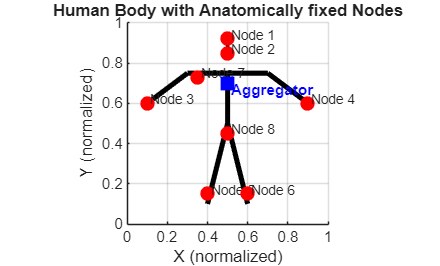

% Abbreviations for Physiological Data
% HR: Heart Rate
% BP: Blood Pressure
% BT: Body Temperature
% RR: Respiratory Rate
% BS: Blood Sugar
% SPO2: Oxygen saturation
% EDA: Electrodermal Activities
% BVP: Blood Volume Pulse


% Sensor node positions (normalized to [0,1])
% Format: [x, y]
nodePositions = [
    0.5, 0.92;   % Node 1 - Head for EDA
    0.5, 0.85;   % Node 2 - Neck for RR
    0.1, 0.6;    % Node 3 - Left wrist for HR
    0.9, 0.6;    % Node 4 - Right wrist for BP
    0.4, 0.15;   % Node 5 - Left knee for BVP
    0.6, 0.15;   % Node 6 - Right knee for SPO2
    0.35, 0.73;  % Node 7 - Left armpit for BT
    0.5, 0.45    % Node 8 - Lower abdomen for BS
];

aggregatorNode = [0.5, 0.7]; % Aggregator on chest

% Create figure
Node_Placement = figure;
figure;
hold on;
axis equal;
grid on;
set(gca, 'xtick', 0:0.2:1, 'ytick', 0:0.2:1);
xlim([0 1]);
ylim([0 1]);
title('Human Body with Anatomically fixed Nodes', 'FontWeight', 'bold');

% Draw human body
% Head
rectangle('Position', [0.475, 0.89, 0.05, 0.05], 'Curvature', [1 1], 'FaceColor', [0.85 0.85 0.85]);

% Neck
plot([0.5, 0.5], [0.89, 0.86], 'k', 'LineWidth', 2);

% Shoulders
plot([0.3, 0.7], [0.75, 0.75], 'k', 'LineWidth', 3);

% Torso
plot([0.5, 0.5], [0.75, 0.5], 'k', 'LineWidth', 3);

% Arms
plot([0.3, 0.1], [0.75, 0.6], 'k', 'LineWidth', 3); % Left
plot([0.7, 0.9], [0.75, 0.6], 'k', 'LineWidth', 3); % Right

% Legs
plot([0.5, 0.4], [0.5, 0.1], 'k', 'LineWidth', 3); % Left
plot([0.5, 0.6], [0.5, 0.1], 'k', 'LineWidth', 3); % Right

% Plot sensor nodes
for i = 1:size(nodePositions, 1)
    plot(nodePositions(i,1), nodePositions(i,2), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
    text(nodePositions(i,1)+0.015, nodePositions(i,2)+0.015, sprintf('Node %d', i), 'FontSize', 8);
end

% Plot aggregator node
plot(aggregatorNode(1), aggregatorNode(2), 'bs', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
text(aggregatorNode(1)+0.015, aggregatorNode(2)-0.035, 'Aggregator', ...
    'FontSize', 9, 'FontWeight', 'bold', 'Color', 'b');

% Axis labels (optional)
xlabel('X (normalized)');
ylabel('Y (normalized)');

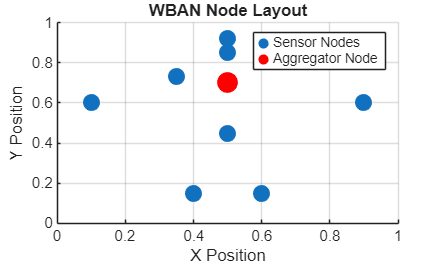


% End of Human and nodes positions

% Plot node positions
figure;
scatter(nodePositions(:,1), nodePositions(:,2), 100, 'filled');
hold on;
scatter(aggregatorNode(1), aggregatorNode(2), 150, 'r', 'filled');
legend('Sensor Nodes', 'Aggregator Node');
title('WBAN Node Layout');
xlabel('X Position'); ylabel('Y Position');
grid on;


% Node Initialization
roles = [repmat("Relay", 1, numRelays), repmat("Source", 1, numSources), "Sink"];
positions = rand(numNodes, 2) * areaSize;
energyOriginal = initialEnergy * ones(numNodes, 1);
sinkID = numNodes;